# Linear Control Design II - Group Work Problem Module 20


$$\matrix{\text{Roberto\,Galeazzi,\,Remus\,Mihail\,Prunesco\,\&\,Leon\,Nagel} \cr
\text{Department\,of\,Electrical\,Engineering}
\cr
\text{Technical\,University\,of\,Denmark} \cr
\text{October,\,2015} \cr
\text{Thomas\,Paulsen} \cr
\text{September,\,2017}}$$


## Description

Module 20 focuses on experiments with white noise. It is often necessary to calculate the average and root mean square (rms) values of a stochastic signal during simulations. Problem 6.5 in the textbook addresses the solution of this issue, which is based on the construction of two differential equations that can do this on line. These solutions are given below:


$$\frac{dv_{avg}}{dt}=\frac{1}{t}(-v_{avg}+u) \qquad (1)$$


where *v_avg* is the average value and *u* is the input. The rms value of a signal can be found from equation:


$$\frac{dv_{rms}}{dt}=\frac{1}{2t}(-v_{rms}+\frac{1}{v_{rms}}u^2) \qquad (2)$$


**Problem 1**

Given the formulas in Problem 6.5, show how Equations 1 and 2 can be obtained.

a. What is the mathematical relation between the rms value of a signal and the statistical parameters of the signal (mean and variance)?

b. Equations 1 and 2 are two scalar linear time-varying systems. Are they asymptotically stable? Do they represent a practical solution to the averaging problem?

c. What is their main failing?

**Solution****:**

The derivation of the differential equations are done by differentiation of the two equation given in problem 6.5 on page 426 leading to


$$\frac{d}{dt}\left(V_{avg}\right)=\frac{d}{dt}\left(\frac{1}{t}\int^t_{t_0}(v(t)dt)\right)\Rightarrow \dot{V}_{avg}=-\frac{1}{t^2}\int^t_{t_0}(v(t)dt)+\frac{1}{t}(v(t)-v(t_0))\Rightarrow \dot{V}_{avg}=-\frac{1}{t}V_{avg}+\frac{1}{t}v(t)$$


By realising that 􀀀 


$$-\frac{1}{t^2}\int^t_{t_0}(v(t)dt)=-\frac{1}{t}V_{avg}$$


and assuming $v(t_0)$=0. This can be done similarly for $V_{rms}$


$$\frac{d}{dt}\left(V_{rms}\right)=\frac{d}{dt}\left(\frac{1}{t}\int^t_{t_0}v(t)^2dt\right)^{\frac{1}{2}}\Rightarrow \dot{V}_{rms}=\frac{1}{2}\left(\frac{1}{t}\int^t_{t_0}v(t)^2dt\right)^{-\frac{1}{2}}\left[-\frac{1}{t^2}\int^t_{t_0}v(t)^2dt+\frac{1}{t}v(t)^2-v(t_0)^2 \right]\Rightarrow \dot{V}_{rms}=\frac{1}{2V_{rms}}\left[-\frac{1}{t}V_{rms}^2+\frac{1}{t}v(t)^2\right]\Rightarrow \dot{V}_{rms}=-\frac{1}{2t}V_{rms}+\frac{1}{2tV_{rms}}v(t)^2$$


this is done similarly by using the deffinition of $V_{rms}$ and substitution for the integral expression along with the assumption $v(t_0)^2$=0.

**1 a)**

The deffinition of the rms value is given in the book on page 358 as:


$$X_{rms} = \sqrt{E\{X^2\}}$$


the deffinition of the variance *sigma_x*^2 is given on page 358 in the book as:


$$\sigma_x^2 = E\{X^2\}-E\{X\}^2 \Rightarrow E\{X^2\}=\sigma_x^2 +E\{X\}^2$$


by substitution of *E{X*^2*}* into the expression of the RMS and exchanging $E\{X\}^2=m^2$ the relation is found as:


$$X_{rms} = \sqrt{\sigma_x^2+m^2}$$


The rms value of a stochastic signal is actually the square root of its squared mean value (D.C. power) plus its variance (A.C. power).

**1 b)**

When analysing state stability the input can be set to zero resulting in:


$$\dot{V}_{avg}=-\frac{1}{t}V_{avg} \Rightarrow \frac{dV_{avg}}{dt}=-\frac{1}{t}V_{avg}$$



$$\dot{V}_{rms}=-\frac{1}{2t}V_{rms} \Rightarrow \frac{dV_{rms}}{dt}=-\frac{1}{2t}V_{rms}$$


this can be solved by seperation of the variables and integration as:


$$\int_{V_{avg}(0)}^{V_{avg}(t)}\left(\frac{1}{V_{avg}}dV_{avg}\right) = -\int_{t_0}^t\left(\frac{1}{t}dt\right)$$



$$\int_{V_{rms}(0)}^{V_{rms}(t)}\left(\frac{1}{V_{rms}}dV_{rms}\right) = -\frac{1}{2}\int_{t_0}^t\left(\frac{1}{t}dt\right)$$


this leads to


$$\ln(V_{avg}(t))-\ln(V_{avg}(0))=-(\ln(t)-\ln(t_0)) \Rightarrow \ln\left(\frac{V_{avg}(t)}{V_{avg}(0)}\right)=\ln\left(\frac{t_0}{t}\right) \Rightarrow V_{avg}(t)=V_{avg}(0)\frac{t_0}{t}$$



$$\ln(V_{rms}(t))-\ln(V_{rms}(0))=-\frac{1}{2}(\ln(t)-\ln(t_0)) \Rightarrow \ln\left(\frac{V_{rms}(t)}{V_{rms}(0)}\right)=\frac{1}{2}\ln\left(\frac{t_0}{t}\right) \Rightarrow V_{rms}(t)=V_{rms}(0)\frac{1}{2}\frac{t_0}{t}$$


From which is can be seen that for $\lim_{t\rightarrow\inf}V_{avg}(t)\rightarrow0$ and $\lim_{t\rightarrow\inf}V_{rms}(t)\rightarrow0$ thus both differential equations are asymptotically stable.

**1 c)**

The infinite time required for the averaging and the cutoff of the averaging effect at large times is their main failing.

**Problem 2**

Use the Equations 1 and 2 to calculate the mean and variance of the signals from the Uniform, *U*(0.5,1/2), and Gaussian distributed (Random Number) noise generators of the Matlab/Simulink package. The notation *U*(0.5,1/2) means uniformly distributed with a mean value 0.5 and variance 1/2 ($\sigma$); whereas *N*(0,1) means normally distributed with a mean value of 0 and a variance of 1 ($\sigma$). Use a generator sample time of 1 s, simulate over 100 s and plot the results. Then use a sample time of 0.1 s and simulate over 10 s. The variable *t* can be obtained by using the clock in the Simulink *Source* menu. Simulate over a time interval which is sufficient to obtain a reasonably smooth response and try different noise generator seeds and sample times. Use the standard integration routine rk45 (Runga Kutta).

a. Do simulation results agree with what is expected? Are the obtained mean and standard deviations correct? Explain.

**Solution****:**

The averaging differential equations are easily realized in Simulink if it is remembered that the terms which must be realized in front of the integrator are those that occur on the right hand side of the differential equations inside the internal feedback loop.

**2 a)**

The results of averaging the Random Number (Gaussian noise), or the Uniform (Distributed) Random Number, do change with the value of the seed selected. This is because there is some statistical variation in the output of the generators. This variation can be eliminated if the generators outputs for many different seeds are averaged. It is only the mean values (calculated over long time intervals) of the generator outputs which are well defined.

tc = 100;
vstd = 1;
vmean =0;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% for uniform distribution sigma^2 = 1/12*(b-a)
%                           mu = 1/2*(a+b)
%                           a = mu - sigma*sqrt(3)
%                           b = mu + sigma*sqrt(3)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

nmax = vmean +vstd*sqrt(3);
nmin = vmean -vstd*sqrt(3);

varexp = vstd^2;

for i = 1:1 % change the range of the counter i in ordet to try different generator seeds
    seed = i*11;
    [t1,x1,y1] = sim('m13solm',[0.01 1000]);
    xs(i,:,:) = x1(:,:);
    ys(i,:,:) = y1(:,:);
end

xm = mean(xs,1);
ym = mean(ys,1);

varmeas = var(ys(1,:,3))

varmeas =       0.98168


mmeas = mean(ys(1,:,3))

mmeas =    0.00073367


mm = mean(ys(1,end/2:end,1))

mm =      0.024488


mrms = mean(ys(1,end/2:end,2))

mrms =        1.0007



vrmsexp = sqrt(vmean^2 + vstd^2)

vrmsexp =      1


vrmsmeas = sqrt(mmeas^2 + varmeas)

vrmsmeas =        0.9908


varmm = mrms^2-mm^2

varmm =        1.0008


**Problem 3**

Instead of t in the equations above, use a time constant $\tau$=100 s. Simulate the differential equations using this simpliffication.

a. Do the results of this simulation agree with those found in Problem 2? Explain.

b. What is the practical application of your results?

**Solution****:**

If one uses a time constant, , instead of the time in the differential equations then one is using a real low pass filter instead of the ideal one implied by the definitions from which the equations are derived. This has no effect on the results obtained for the average and rms values measured as long as the time constant is much longer than the sampling time of the noise generators. The time constant should be on the order of 20 to 50 times the sampling time.

**3 a)**

Thus the results of the simulation with a time constant do agree with those obtained with the ideal filters of the primary differential equations.

**3 b)**

The practical application of the results obtained is that it is possible to build true rms instruments which work in actual applications. In fact all real rms instruments work with some averaging time.

[tsc,xsc,ysc] = sim('m13solm3',[0.01 1000]);
varmeasc = var(ysc(:,3))

varmeasc = 0.9902

mmeasc = mean(ysc(:,3))

mmeasc = -0.0017

mmc = mean(ysc(end/2:end,1))

mmc = -0.0351

mrmsc = mean(ysc(end/2:end,2))

mrmsc = 0.9950

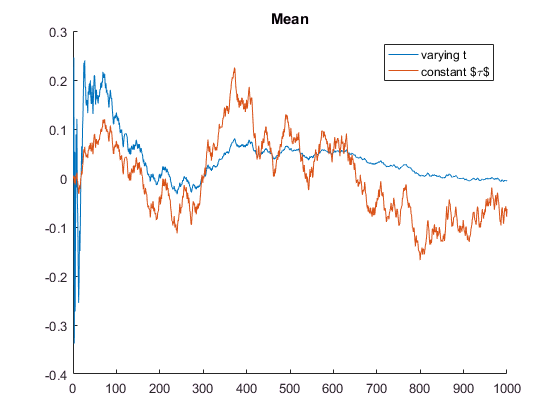


figure
hold all
plot(t1,ym(1,:,1));
plot(tsc,ysc(:,1))
legend('varying t','constant $\tau$');
title('Mean');

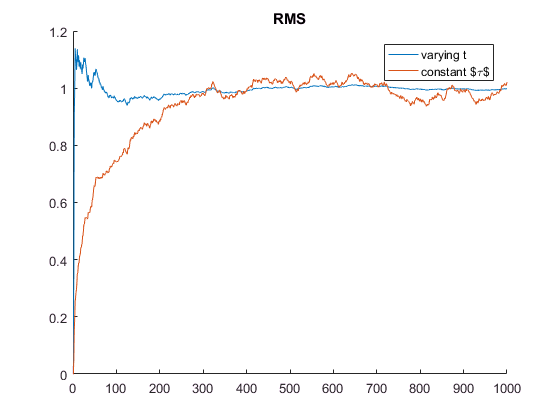


figure
hold all
plot(t1,ym(1,:,2));
plot(tsc,ysc(:,2))
legend('varying t','constant $\tau$');
title('RMS');

**Problem 4**

Add two different noise signals together (different seeds and variances) and use Equations 1 and 2 to find their means and standard deviations.

a. What do the results show about the rule for adding noise signals?

**Solution****:**

When adding to different noise signals together the resulting noise signal will have mean and variance equal to the sum of the means and variances. This is described on page 368 in the book.

seed2 = 345;
vstd2 = 0.5;
vmean2 =0.5;
nmax2 = vmean2 +vstd2*sqrt(3);
nmin2 = vmean2 -vstd2*sqrt(3);
[tss,xss,yss] = sim('m13solm4',[0.01 5000]);

mmeass = mean(yss)

mmeass =     0.4977    1.2255    0.5089    0.0044    0.5045


mms = mean(yss(end/2:end,1))

mms = 0.5064

mrmss = mean(yss(end/2:end,2))

mrmss = 1.2277

exprmss = sqrt(vstd2^2+vstd^2+(vmean2+vmean)^2)

exprmss = 1.2247

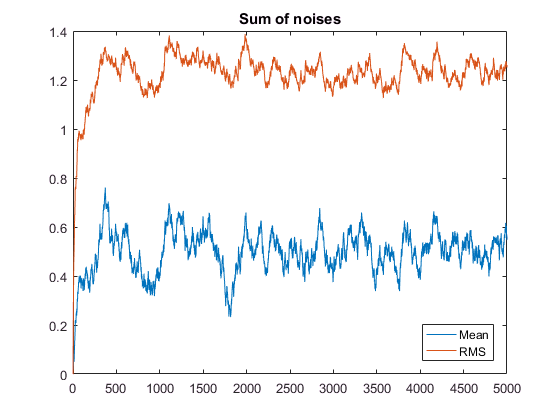


figure
plot(tss,yss(:,1:2))
title('Sum of noises');
legend('Mean','RMS','location','southeast');

**Problem 5**

Assume that the available noise generators can deliver an approximation to white noise.

a. Construct a Wiener Process and use two such processes to construct a random walk process in two dimensions. Demonstrate graphically that this two dimensional process works as expected. Compare your results to those in Figures 6.11-6.13 in the textbook.

**Solution****:**

**5 a)**

Result of the simulation is shown in Figure 1, the implementation can be found in the matlab simulink files.

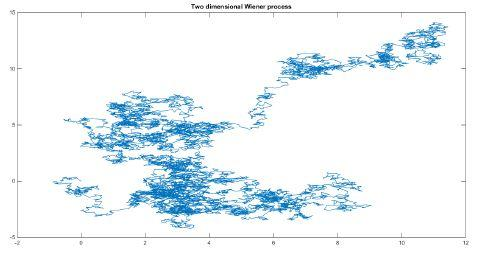


$$Figure\,1:\,Simulation\,of\,a\,two\,dimensional\,Wiener\,process.$$


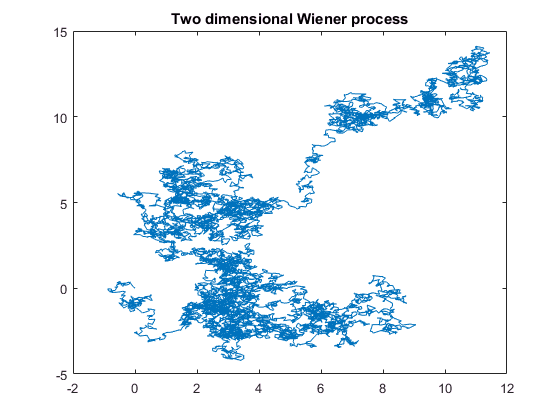

seed61 = 123;
seed62 = 456;

[t6,x6,y6] = sim('m13sol6',[0.01 1000]);
figure
plot(x6(:,1),x6(:,2));
title('Two dimensional Wiener process');

**Further Experiments with White Noise**

In this exercise the work started in Group Work Exercise 13 will be continued with the study of a second order low pass filter and the noise calculated using the Lyapunov equation. Consider a second order low pass filter ($\omega_0$=10 rad/s and $\zeta$=0.707)


$$\matrix{\dot{x}=v \cr \dot{v}=-\omega_0^2x-2\zeta\omega_0v+\omega^2_0 \cr y=x } \qquad (3)$$


driven by band-limited noise *u* with autocorrelation function


$$\textbf{R}(\tau)=\sigma^2_u\text{e}^{-\beta|\tau|}$$


 where $\sigma^2_u$=0.5 and $\beta$=10.

**Problem 6**

Using the Lyapunov equation find theoretical value of the covariance matrix **Q** as a function of the system parameters. Then solve numerically the Lyapunov equation using the Matlab command *lyap()*.

**Solution****:**

The second order low pass filter is a time invariant stable system, hence the propagation of white noise through this system can be studied by setting up the steady state Lyapunov equation


$$\mathbf{AQ}_{\inf}+\mathbf{Q}_{\inf}\mathbf{A}^\text{T}+\mathbf{B}_v\mathbf{V}\mathbf{B}_v^\text{T}=0\qquad(18)$$


where $\mathbf{Q}_{inf}$ is the steady state covariance matrix, which is symmetric and positive definite


$$\left(\mathbf{Q}_{\inf}=\mathbf{Q}_{\inf}^\text{T}>0\right)$$


The lyapunove equation is based on the assumption of white noise, however the input signal u is not white noise, but it is band-limited noise with a given autocorrelation function *R(*$\tau$); therefore Equation 18 cannot be directly applied to the given system. However the band-limited noise *u* with autocorrelation *R*($\tau$) can be seen as the result of passing white noise $\omega$ with noise power equal to 1 through the filter


$$S(\omega)=\frac{2\sigma^2\beta}{\beta^2+\omega^2}$$


this can also be written as


$$S(\omega)=G(\omega)\tilde{S}$$


where $\tilde{S}\in N_{iid}(0,1)$ and $G(\omega)=\frac{2\sigma^2\beta}{\beta^2+\omega^2}$ if the variable $\omega^2$ is rewritten as 􀀀 $(j\omega)^2$ then $G(\omega)$ can be expressed as


$$G(\omega)=\frac{\sqrt{2\beta}\sigma}{\beta+j\omega}\frac{\sqrt{2\beta}\sigma}{\beta-j\omega}$$


This expressed the fourier transform as


$$S(j\omega)=\tilde{G}(j\omega)\tilde{S}\tilde{G}(-j\omega)$$


substituting $s=j\omega$ and considering only the stable filter results in the band-limited noise *u* being created as a white noise process sent through the filter:


$$H(s)=\frac{\sqrt{2\beta}\sigma_u}{s+\beta}$$


Hence the evaluation of the noise propagation through the second order low pass filter can still be done with the Lyapunov equation if first we augment the system as follows (augmented state vector $\mathbf{x}_a = [u,x,v]^\text{T}$)


$$\matrix{\dot{u}=-\beta u+\sqrt{2\beta}\sigma_uw\cr\dot{x}=v\cr\dot{v}=-\omega_0^2x-2\zeta\omega_0v+\omega_0^2u}$$


The steady state Lyapunov equation in matrix form then reads ($v = 1$)


$$\left[\matrix{-\beta&0&0\cr 0&0&1\cr \omega_0^2&-\omega_0^2&-2\zeta\omega_0}\right] \left[\matrix{q_{11}&q_{12}&q_{13}\cr q_{12}&q_{22}&q_{23}\cr q_{13}&q_{23}&q_{33}}\right] + \left[\matrix{q_{11}&q_{12}&q_{13}\cr q_{12}&q_{22}&q_{23}\cr q_{13}&q_{23}&q_{33}}\right] \left[\matrix{-\beta&0&\omega_0^2\cr 0&0&-\omega_0^2\cr 0&1&-2\zeta\omega_0}\right] + \left[\matrix{\sqrt{2\beta}\sigma_u\cr 0\cr 0}\right] \left[\matrix{\sqrt{2\beta}\sigma_u&0&0}\right] = \left[\matrix{0&0&0\cr 0&0&0\cr 0&0&0}\right]$$


which gives rise to the following six algebraic equations in the unknowns $q_{ij}$


$$\matrix{-2\beta q_{11}+2\beta\sigma_u^2=0\cr q_{13}-\beta q_{12}=0\cr -\beta q_{13}-2\zeta\omega_0\beta q_{13}+\omega_0^2 q_{11}-\omega_0^2 q_{12}=0\cr 2q_{23}=0\cr q_{33}-2\zeta\omega_0 q_{23}+\omega_0^2 q_{12}-\omega_0^2 q_{22}=0\cr -4\zeta\omega_0 q_{33}+2\omega_0^2 q_{13}-2\omega_0^2 q_{23}=0}$$


The solution can be found to be


$$\matrix{q_{11}=\sigma_u^2\cr q_{12}=\frac{\omega_0^2}{\beta^2+2\beta\zeta\omega_0+\omega_0^2}\sigma_u^2\cr q_{13}=\frac{\beta\omega_0^2}{\beta^2+2\beta\zeta\omega_0+\omega_0^2}\sigma_u^2\cr q_{22}=\sigma_x^2=\frac{\beta\omega_0+2\zeta\omega_0^2}{2\zeta(\beta^2+2\beta\zeta\omega_0+\omega_0^2)}\sigma_u^2\cr q_{23}=0\cr q_{33}=\sigma_v^2=\frac{\beta\omega_0^3}{2\zeta(\beta^2+2\beta\zeta\omega_0+\omega_0^2)}\sigma_u^2}$$


and the covariance matrix $\mathbf{Q}_{\inf}$ reads


$$\mathbf{Q}_{\inf}=\left[\matrix{\sigma_u^2&\frac{\omega_0^2}{\beta^2+2\beta\zeta\omega_0+\omega_0^2}\sigma_u^2&\frac{\beta\omega_0^2}{\beta^2+2\beta\zeta\omega_0+\omega_0^2}\sigma_u^2 \cr \frac{\omega_0^2}{\beta^2+2\beta\zeta\omega_0+\omega_0^2}\sigma_u^2&\sigma_x^2=\frac{\beta\omega_0+2\zeta\omega_0^2}{2\zeta(\beta^2+2\beta\zeta\omega_0+\omega_0^2)}\sigma_u^2 &0 \cr \frac{\beta\omega_0^2}{\beta^2+2\beta\zeta\omega_0+\omega_0^2}\sigma_u^2&0 &\sigma_v^2=\frac{\beta\omega_0^3}{2\zeta(\beta^2+2\beta\zeta\omega_0+\omega_0^2)}\sigma_u^}\right]=\left[\matrix{0.5&0.14646&1.4646\cr 0.14646&0.25003&0\cr 1.4646&0&10.358}\right]\qquad(40)$$


The diagonal elements of the covariance matrix $\textbf{Q}_{\inf}$ are the variances of the individual state variables indicating how large the deviations will be with respect to the mean values of the states. The off-diagonal terms provide instead an **absolute measure of linear correlation among the state variables**. In particular it can be noted that 

the state variables *x* and *v* are correlated with the noise input *u*, and to positive variations of *u* correspond positive variations of *x* and *v* (this can be seen from $q_{12}>0$ and $q_{13}>0$). The correlation between *u* and *v*, and between *u* and *x* is certainly expected since the state variables are affected by the noise source

the state variables *x* and *v* are not correlated because they are orthogonal; in fact  the integral/differential operator always introduces a phase shift of 90 degrees.

The same result shown in Equation 40 is obtained by using the Matlab command *lyap()* as illustrated in the following script

% System description
w = 10;
zeta = 0.707;
sigma_u = sqrt(0.5);
beta = 10;
V = 1;

A = [0 1;-w^2 -2*zeta*w];
B = [0 w^2]';
C = [1 0];

Aa = [-beta 0 0;0 0 1;w^2 -w^2 -2*zeta*w];
Ba = [sqrt(2*beta)*sigma_u 0 0]';
Q = Ba*V*Ba';

% Solution of the Lyapunov equation for calculating the noise amplitudes
lyap(Aa,Q)

ans =     0.5000    0.1465    1.4646
    0.1465    0.2500    0.0000
    1.4646    0.0000   10.3576


**Problem 7**

Implement a Simulink model representing Equation 3 and simulate it for at least 1000 seconds. Export the input, the states and the output, and calculate the statistical properties of these signals. Compare the obtained results with those of Problem 1 and comment on them.

**Solution****:**

The calculation of the statistical properties of the state variables based on simulated/measured data is strongly affected by the length (number of samples) of the available data set, as shown in the following three test cases:

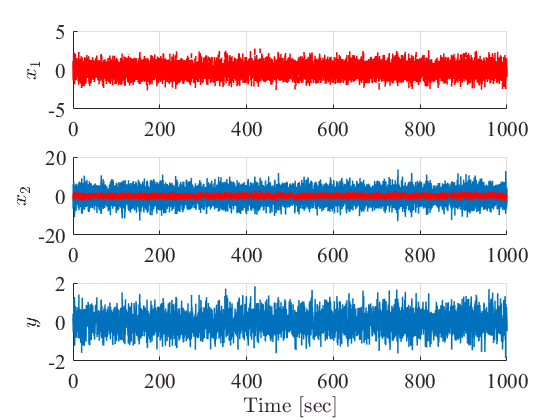

% Simulating the system
sim('gp14_simulink',1000);

u = logsout.getElement(1).Values.Data;
x = logsout.getElement(3).Values.Data(:,1);
v = logsout.getElement(3).Values.Data(:,2);
y = logsout.getElement(2).Values.Data;
mX = logsout.getElement(4).Values.Data;
mV = logsout.getElement(5).Values.Data;
rmsX = logsout.getElement(6).Values.Data;
rmsV = logsout.getElement(7).Values.Data;
t = logsout.getElement(1).Values.Time;

figure, h1 = subplot(3,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(t,x,t,u,'--r','LineWidth',1); % state 1 output
ylabel('$$x_1$$','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(3,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(t,v,t,u,'--r','LineWidth',1); % state 2 output
ylabel('$$x_2$$','FontName','times','FontSize',16,'Interpreter','latex')
h3 = subplot(3,1,3); set(h3,'FontName','times','FontSize',16)
hold on, grid on 
plot(t,y,'LineWidth',1); % original noise signal
ylabel('$$y$$','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')


% Numerical evaluation of the solution of the Lyapunov equation
Qmeas = cov([u x v])

Qmeas =     0.4810    0.1356    1.4312
    0.1356    0.2359    0.0009
    1.4312    0.0009   10.0512


However for an ergodic process in the limit of time going to infinity the time average will match the ensemble average (Section 6.3.4 of the textbook), hence the longer we simulate/acquire data the closer the measured covariance matrix is to the theoretical covariance matrix $\textbf{Q}_{\inf}$.